# Problem 9

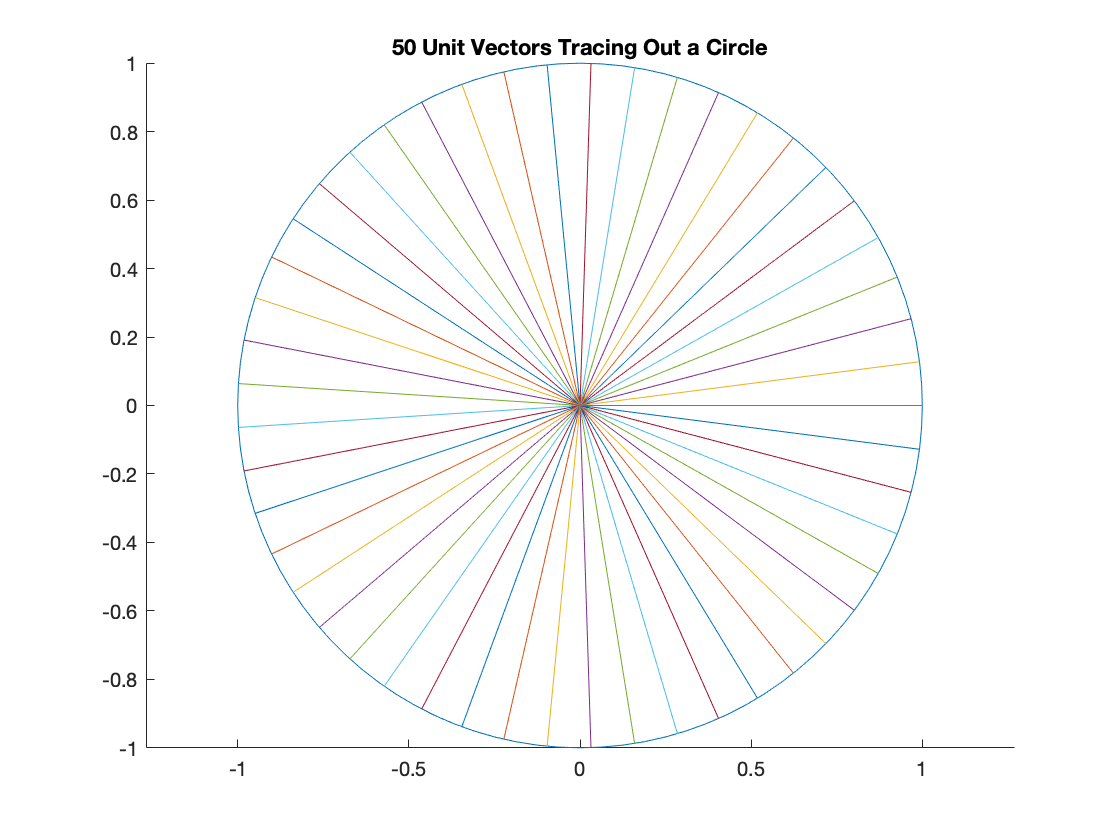

ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


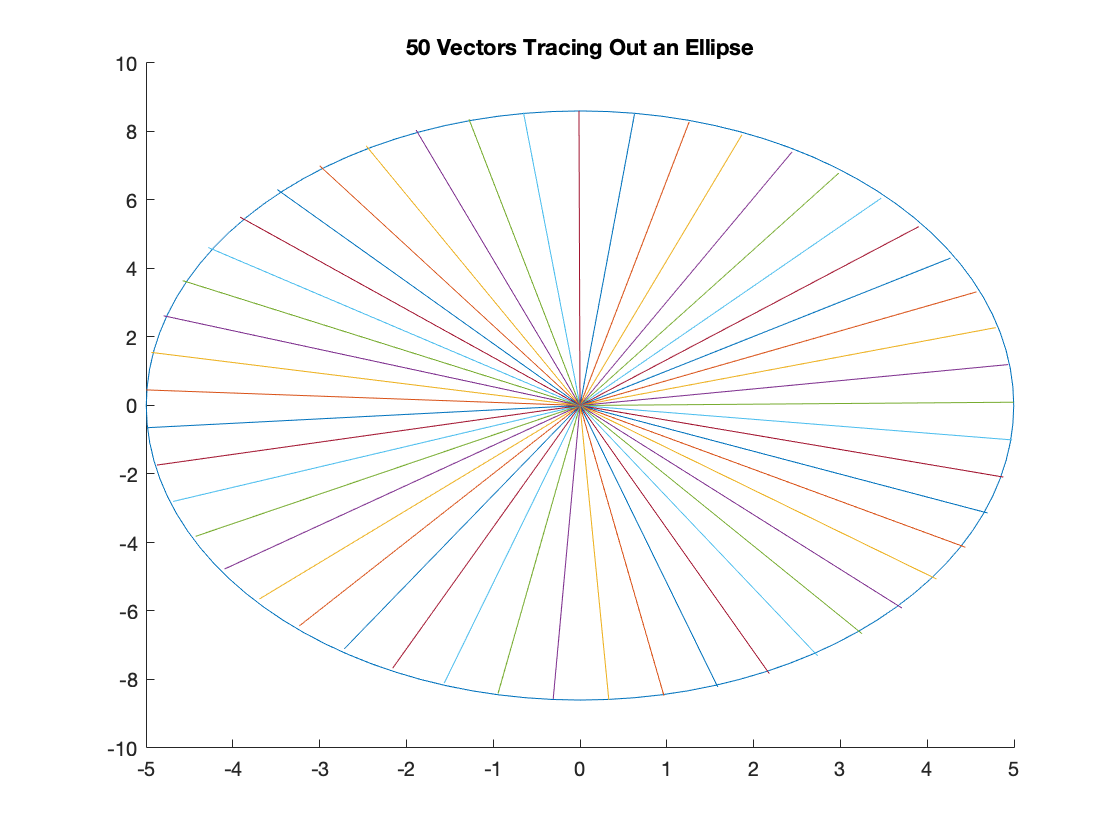

clear; close all; clc;

A = [-3, 4; 7, 5];
newplot
matrixTransformationOnUnitCircle(A)

function matrixTransformationOnUnitCircle(A)

%%% I could'n find out why I cannot plot two graphs in one funciton. %%%


theta = linspace(0, 2*pi, 50); % 1*50 row vector
r = 1;
x = r*cos(theta); % 1*50 row vector
y = r*sin(theta); % 1*50 row vector
o = zeros(size(theta));

M = [x;y]; % 50 columns of 2*1 unit vectors 
%% A = [-3, 4; 7, 5]; % A is the matrix in the problem 
B = A*M; % B stores all 2*1 vectors in M, after multiply them by A

%% Before Matrix Transformation
newplot
title('50 Unit Vectors Tracing Out a Circle')
ellipse(1,1)
plot([o' x']', [o' y']')
axis equal
hold off


X = B(1,:); % Get the first row --- x component, from B
Y = B(2,:); % Get the second row --- y component, from B
maxX = max(X);
maxY = max(Y);
%% After Matrix Transformation 
newplot
title('50 Vectors Tracing Out an Ellipse')
ellipse(maxX, maxY)
plot([o' X']', [o' Y']')
hold off
end


function h = ellipse(r1, r2)
hold on
th = 0:pi/50:2*pi;
xunit = r1 * cos(th);
yunit = r2 * sin(th);
h = plot(xunit, yunit);
end
%% c.f. MathWorks Plot a Circle & Ellipse --- I combined them.